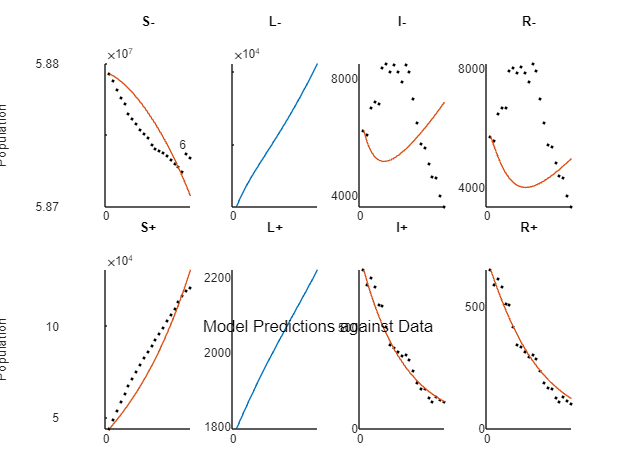


% 2 X 4

load("/MATLAB Drive/ProjectSLIRS/Ali/data_uk.mat")



time = 22; t = 1:1:time;
beta_n = 10e-9;              % DP to R and I, IP to S
epsilon_n = 3.5e-1;          % DP to I, IP to R
gamma_n = 8e-1;%0.0396;     % DP to R, IP to I
lambda_n =  2.5e-2;

beta_p = 4e-6;             % DP to , IP to
epsilon_p = 2e-1;           % DP to S, IP to R
gamma_p = 8.18e-2;             % DP to , IP to I
lambda_p = 2.5e-3;
delta = 8.85e-10;


L_n_0 = 9.5e4;
L_p_0 = 4.58e3;  

% epsilon_n = 0.2876;
gamma_n = 0.2599;
beta_p = 0.00000071956;
epsilon_p = 0.1804;
gamma_p = 0.0902;
delta = 0.0000000008577;
% lambda_n = 0.0738;
lambda_p = 0.0007125;
L_n_0 = 43087;
L_p_0 = 1794.5;


par = [beta_n, epsilon_n gamma_n beta_p epsilon_p gamma_p delta 0 lambda_n lambda_p];
inital_values = [data(1:1) data(2,1) data(3,1) data(4,1) data(5,1) data(6,1) L_n_0 L_p_0];


model_out = SLIR_free(par, inital_values, time);

close all;
subplot(2,4,1)
hold on
plot(t, data(1,:), 'k.')
plot(t, model_out(1,:)+model_out(7,:))

xlabel('Years'), ylabel('Population')
title('S-')
hold off;

subplot(2,4,2)
hold on;
% plot(t, data(2,:), 'k.')
plot(t, model_out(7,:))
xlabel('Years'), ylabel('Population')
title('L-')
hold off

subplot(2,4,3)
hold on;
plot(t, data(2,:), 'k.')
plot(t, model_out(2,:))
xlabel('Years'), ylabel('Population')
title('I-')
hold off

subplot(2,4,4)
hold on
plot(t, data(3,:), 'k.')
plot(t, model_out(3,:))
xlabel('Years'), ylabel('Population')
title('R-')
hold off;

subplot(2,4,5)
hold on;
plot(t, data(4,:), 'k.')
plot(t, model_out(4,:)+model_out(8,:))
xlabel('Years'), ylabel('Population')
title('S+')
hold off


subplot(2,4,6)
hold on;
% plot(t, data(6,:), 'k.')
plot(t, model_out(8,:))
xlabel('Years'), ylabel('Population')
title('L+')
hold off

subplot(2,4,7)
hold on;
plot(t, data(5,:), 'k.')
plot(t, model_out(5,:))
xlabel('Years'), ylabel('Population')
title('I+')
hold off


subplot(2,4,8)
hold on;
plot(t, data(6,:), 'k.')
plot(t, model_out(6,:))
xlabel('Years'), ylabel('Population')
title('R+')
hold off

sgtitle('Model Predictions against Data')

savefig('ModelPreds.fig')


% % % % % % % % % % % % 3x3 Plot

time = 22;
beta_n =    1e-9;              % DP to R and I, IP to S
epsilon_n = 4e-2;          % DP to I, IP to R
gamma_n =   6e-2;%0.0396;     % DP to R, IP to I
lambda_n =  4.5e-1;

beta_p =    6.5e-5;             % DP to , IP to
epsilon_p = 8e-1;           % DP to S, IP to R
gamma_p =   6.5e-1;             % DP to , IP to I
lambda_p =  5.5e-10;
delta =     6.5e-6;


L_n_0 = 1000;
L_p_0 = 100;


par = [beta_n, epsilon_n gamma_n beta_p epsilon_p gamma_p delta 0 lambda_n lambda_p];
inital_values = [data(1:1) data(2,1) data(3,1) data(4,1) data(5,1) data(6,1) L_n_0 L_p_0];



model_out = SLIR(par, inital_values, time);

close all;
subplot(2,3,1)
hold on
plot(t, data(1,:), 'k.')
plot(t, model_out(1,:)+model_out(7,:))

xlabel('Years'), ylabel('S-')
title('S-')
hold off;


subplot(2,3,2)
hold on;
plot(t, data(2,:), 'k.')
plot(t, model_out(3,:))
xlabel('Years'), ylabel('I-')
title('I-')
hold off

subplot(2,3,3)
hold on
plot(t, data(3,:), 'k.')
plot(t, model_out(4,:))
xlabel('Years'), ylabel('R-')
title('R-')
hold off;

subplot(2,3,4)
hold on;
plot(t, data(4,:), 'k.')
plot(t, model_out(5,:)+model_out(8,:))
xlabel('Years'), ylabel('S+')
title('S+')
hold off


subplot(2,3,5)
hold on;
plot(t, data(5,:), 'k.')
plot(t, model_out(7,:))
xlabel('Years'), ylabel('I+')
title('I+')
hold off


subplot(2,3,6)
hold on;
plot(t, data(6,:), 'k.')
plot(t, model_out(8,:))
xlabel('Years'), ylabel('R+')
title('R+')
hold off



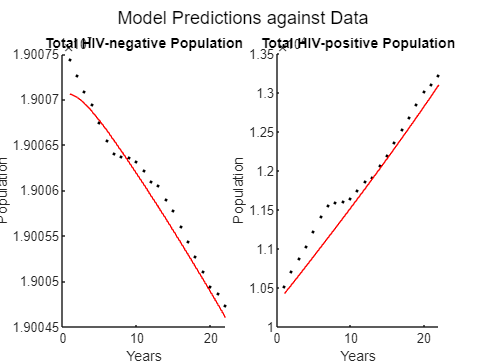

%Total HIV-
subplot(1, 2, 1)
hold on;
plot(t, data(1,:) + data(2,:) + data(3,:), 'k.')
plot(t, model_out(1,:) + model_out(2,:) + model_out(3,:), 'red')
xlabel('Years')
ylabel('Population')
title('Total HIV-negative Population')
hold off;

% Total HIV+
subplot(1, 2, 2)
hold on;
plot(t, data(4,:) + data(5,:) + data(6,:), 'k.')
plot(t, model_out(4,:) + model_out(5,:) + model_out(6,:), 'red')
xlabel('Years')
ylabel('Population')
title('Total HIV-positive Population')
hold off;



%Intervention Analysis

load("../Ali/data_australia.mat");


% Increase in awareness of HIV precautions





time = 22;
beta_n =    1e-9;              % DP to R and I, IP to S
epsilon_n = 4e-2;          % DP to I, IP to R
gamma_n =   6e-2;%0.0396;     % DP to R, IP to I
lambda_n =  4.5e-1;

beta_p =    6.5e-5;             % DP to , IP to
epsilon_p = 8e-1;           % DP to S, IP to R
gamma_p =   6.5e-1;             % DP to , IP to I
lambda_p =  5.5e-10;
delta =     6.5e-6;


L_n_0 = 1000;
L_p_0 = 100;


par = [beta_n, epsilon_n gamma_n beta_p epsilon_p gamma_p delta*(1-alpha) 0 lambda_n lambda_p];
inital_values = [data(1:1) data(2,1) data(3,1) data(4,1) data(5,1) data(6,1) L_n_0 L_p_0];



model_out = SLIR(par, inital_values, time);































